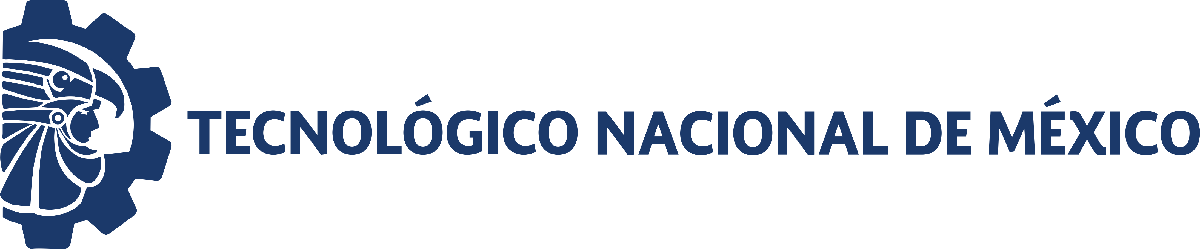                                 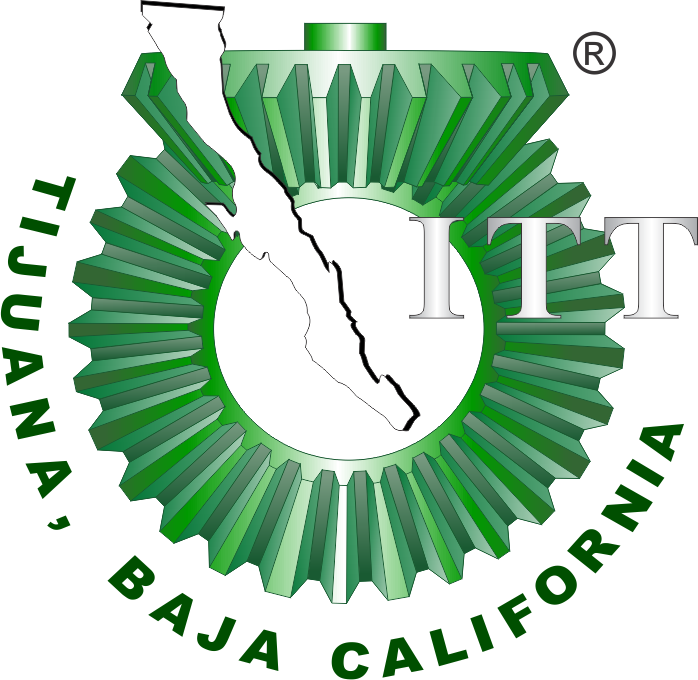

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

# Práctica: Caos en sistemas biológicos

Comparar métodos de diferencias finitas para solucionar sistemas de ODEs no lineales de primer orden que exhiben diferentes conjuntos compactos invariantes para diferentes valores en sus parámetros y/o condiciones iniciales. El modelo matemático está compuesto por las siguientes tres EDOs de primer orden:


$$\dot x = r_1 x (1-b_1x)-a_{12}xy-a_{13}xz
$$



$$\dot y = r_2y(1-b_2y)-a_{21}xy$$



$$\dot z = (r_3-a_{31})xz-d_3z+\rho_i$$


donde la variable de estado $x\left(t\right)$ representa la población de células anormales o patalógicas, la variable de estado $y\left(t\right)$ la población de células normales o sanas y la variable de estado $z\left(t\right)$ población de células efectoras (citotóxicas o NK); la descripción y valores de los parámetros se presenta a continuación:

$r_1 =1:$ Tasa de crecimiento de las células patológicas.

$b_1 =1:$ Capacidad de carga máxima de las células patológicas.

$a_{12} \in \left\lbrack 0,1\right\rbrack :$ Fracción de células patológicas eliminadas por las células sanas.

$a_{13} =2\ldotp 5:$ Fracción de células patológicas eliminadas por células efectoras.

$r_2 =0\ldotp 6:$ Tasa de crecimiento de las células sanas.

$b_2 =1:$ Capacidad de carga máxima de las células sanas.

$a_{21} =1\ldotp 5:$ Fracción de células sanas eliminadas por las células patológicas.

$r_3 =3:$ Tasa de reclutamiento máximo de células efectoras.

$a_{31} =0\ldotp 3:$ Fracción de células efectoras inactivadas por las células patológicas.

$d_3 =0\ldotp 4:$ Tasa de muerte de las células efectoras.

$\rho_i \left(t\right):$ Tratamiento de inmunoterapia.

Cabe destacar que la dinámica del sistema se localiza en octante no negativo definido por el siguiente dominio:


$$\mathbf{R}_{+,0}^{3}=\left\{ x\left( t\right) \geq 0,y\left( t\right) \geq 0,z\left( t\right) \geq 0\right\}$$


El sistema exhibe diferentes dinámicas para distintos valores del parámetro de bifurcación $a_{12}$, como se indica a continuación:

- Un atractor caótico con $a_{12} =1$, en el intervalo de tiempo $t\in \left\lbrack 0,1000\right\rbrack$ y las condiciones iniciales:$\left(x\left(0\right),y\left(0\right),z\left(0\right)\right)=\left(0\ldotp 555,0\ldotp 148,0\ldotp 172\right)\ldotp$

- Una órbita periódica con $a_{12} =0\ldotp 9$, en el intervalo de tiempo $t\in \left\lbrack 0,500\right\rbrack$ y las condiciones iniciales: $\left(x\left(0\right),y\left(0\right),z\left(0\right)\right)=\left(0\ldotp 254781,0\ldotp 115167,0\ldotp 600527\right)\ldotp$

- Un ciclo límite interno con $a_{12} =0\ldotp 8$, en el intervalo de tiempo $t\in \left\lbrack 0,500\right\rbrack$ y las condiciones iniciales: $\left(x\left(0\right),y\left(0\right),z\left(0\right)\right)=\left(0\ldotp 2,0\ldotp 6,0\ldotp 1\right)\ldotp$

- Un ciclo límite externo con $a_{12} =0\ldotp 75$, en el intervalo de tiempo $t\in \left\lbrack 0,500\right\rbrack$ y las condiciones iniciales: $\left(x\left(0\right),y\left(0\right),z\left(0\right)\right)=\left(0\ldotp 4,0\ldotp 2,0\ldotp 4\right)\ldotp$

- Convergencia hacia un punto de equilibrio con $a_{12} =0\ldotp 5$, en el intervalo de tiempo $t\in \left\lbrack 0,500\right\rbrack$ y las condiciones iniciales: $\left(x\left(0\right),y\left(0\right),z\left(0\right)\right)=\left(0\ldotp 5,0\ldotp 5,0\ldotp 4\right)\ldotp$

[Figura representativa del sistema elaborada en BioRender] 

Figura. Generar la figura del sistema presa-depredador con [https://bioart.niaid.nih.gov/](https://bioart.niaid.nih.gov/) o [https://www.biorender.com/](https://www.biorender.com/).

## Referencias

[1] Valle, Paul A., *Syllabus para Biología de Sistemas y Gemelos Digitales*, Tecnológico Nacional de México / Instituto Tecnológico de Tijuana, Tijuana, B.C., México, 2026. Permalink: [https://biomath.xyz/course/](https://biomath.xyz/course/) 

[2] Itik, M., & Banks, S. P. (2010). Chaos in a three-dimensional cancer model. *international Journal of bifurcation and chaos*, *20*(01), 71-79. [https://doi.org/10.1142/S0218127410025417](https://doi.org/10.1142/S0218127410025417)

[3] Bryan, Kurt. *Differential equations: A toolbox for modeling the world*. Simiode, 2022. Permalink: [https://www.simiode.org/resources/8307](https://www.simiode.org/resources/8307) 

## Información general

##                                                              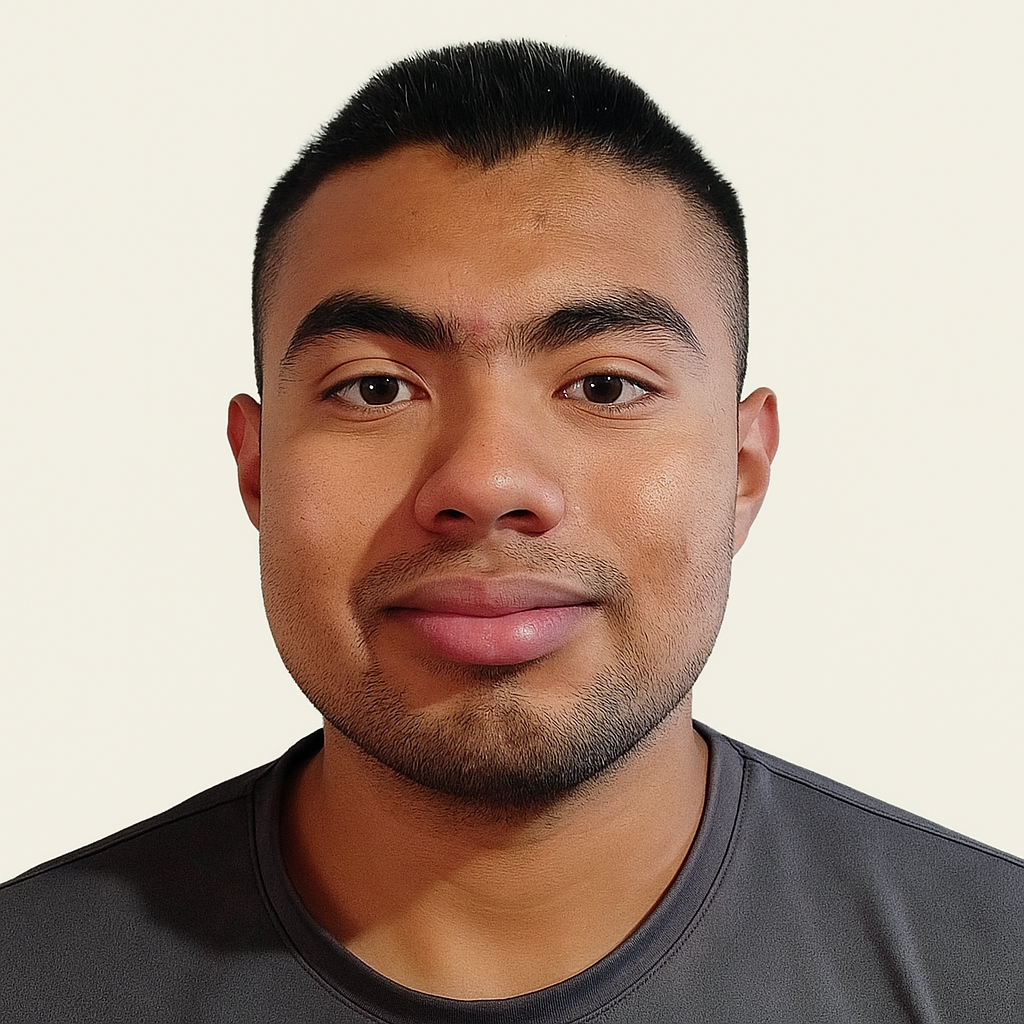

[Foto]

Nombre del alumno: Ricardo Rioda Santiago Sanchez

Número de control: m25210047

Correo institucional: m25210047**@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')

### Comparacion de metodos numericos:

#### Atractor caotico

D = getdata('chaos'); f0 = D.f0; par = D.par;
dt = 1e-4;
tend = 1000;
rhoi_0 = zeros(round(tend/dt)+1,1);

#### Euler

method = 'Euler';

[t,x,y,z] = odesolver(method,f0,par,rhoi_0,tend,dt);

plotEDOs(t,x,y,z);
sgtitle(['Método numérico: ', method]);

exportgraphics(gcf,[method,'_Chaos.pdf'],'ContentType','vector');

#### Heun


%% Heun
method = 'Heun';

[t,x,y,z] = odesolver(method,f0,par,rhoi_0,tend,dt);

plotEDOs(t,x,y,z);
sgtitle(['Método numérico: ', method]);

exportgraphics(gcf,[method,'_Chaos.pdf'],'ContentType','vector');


#### Runge-Kutta


%% Runge-Kutta
method = 'Runge-Kutta';

[t,x,y,z] = odesolver(method,f0,par,rhoi_0,tend,dt);

plotEDOs(t,x,y,z);
sgtitle(['Método numérico: ', method]);

exportgraphics(gcf,[method,'_Chaos.pdf'],'ContentType','vector');


#### Orbita periodica

D = getdata('orbit'); f0 = D.f0; par = D.par;
dt = 1e-4;
tend = 500;
rhoi_0 = zeros(round(tend/dt)+1,1);
method = 'Runge-Kutta';
[t,x,y,z] = odesolver(method,f0,par,rhoi_0,tend,dt);
plotEDOs(t,x,y,z); sgtitle(['Método numérico: ', method]);...
    exportgraphics(gcf,[method,'_Orbit.pdf'],'ContentType','vector')

#### ciclo limite interno

D = getdata('cyclei'); f0 = D.f0; par = D.par;
dt = 1e-4;
tend = 500;
rhoi_0 = zeros(round(tend/dt)+1,1);
method = 'Runge-Kutta';
[t,x,y,z] = odesolver(method,f0,par,rhoi_0,tend,dt);
plotEDOs(t,x,y,z); sgtitle(['Método numérico: ', method]);...
    exportgraphics(gcf,[method,'_CycleI.pdf'],'ContentType','vector')

#### ciclo limite externo

D = getdata('cyclee'); f0 = D.f0; par = D.par;
dt = 1e-4;
tend = 500;
rhoi_0 = zeros(round(tend/dt)+1,1);
method = 'Runge-Kutta';
[t,x,y,z] = odesolver(method,f0,par,rhoi_0,tend,dt);
plotEDOs(t,x,y,z); sgtitle(['Método numérico: ', method]);...
    exportgraphics(gcf,[method,'_CycleE.pdf'],'ContentType','vector')

#### Punto de equilibrio

D = getdata('equilibrium'); f0 = D.f0; par = D.par;
dt = 1e-4;
tend = 500;
rhoi_0 = zeros(round(tend/dt)+1,1);
method = 'Runge-Kutta';
[t,x,y,z] = odesolver(method,f0,par,rhoi_0,tend,dt);
plotEDOs(t,x,y,z); sgtitle(['Método numérico: ', method]);...
    exportgraphics(gcf,[method,'_Equilibrium.pdf'],'ContentType','vector')

#### Calculo de equilibrios

clc; clear; close all; warning('off','all')
syms x y z
syms r1 b1 a12 a13
syms r2 b2 a21
syms r3 a31 d3 rho

dx = r1*x*(1 - b1*x) - a12*x*y - a13*x*z == 0;
dy = r2*y*(1 - b2*y) - a21*x*y == 0;
dz = (r3 - a31)*x*z - d3*z + rho == 0;

Eqs = solve([dx,dy,dz],[x,y,z]);

fprintf(['Puntos de equilibrio del sistema: ', ...
    num2str(length(Eqs.x))]);

Puntos de equilibrio del sistema: 6


for i = 1:length(Eqs.x)
    % disp([Eqs.x(i); Eqs.y(i); Eqs.z(i)])
    disp([simplify(Eqs.x(i)); simplify(Eqs.y(i)); simplify(Eqs.z(i))])
end

$$\begin{array}{l} \left(\begin{array}{c} \frac{a_{31}\,r_{1}-r_{1}\,r_{3}+\sigma_{1}-b_{1}\,d_{3}\,r_{1}}{2\,b_{1}\,r_{1}\,\left(a_{31}-r_{3}\right)}\\ 0\\ \frac{a_{31}\,r_{1}-r_{1}\,r_{3}-\sigma_{1}+b_{1}\,d_{3}\,r_{1}}{2\,a_{13}\,\left(a_{31}-r_{3}\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{r_{1}\,\left(r_{1}\,{a_{31}}^{2}+2\,r_{1}\,a_{31}\,b_{1}\,d_{3}-4\,a_{13}\,\rho \,a_{31}\,b_{1}-2\,r_{1}\,a_{31}\,r_{3}+r_{1}\,{b_{1}}^{2}\,{d_{3}}^{2}-2\,r_{1}\,b_{1}\,d_{3}\,r_{3}+4\,a_{13}\,\rho \,b_{1}\,r_{3}+r_{1}\,{r_{3}}^{2}\right)} \end{array}$$

$$\left(\begin{array}{c} 0\\ \frac{1}{b_{2}}\\ \frac{\rho }{d_{3}} \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{c} -\frac{r_{1}\,r_{3}-a_{31}\,r_{1}+\sigma_{1}+b_{1}\,d_{3}\,r_{1}}{2\,b_{1}\,r_{1}\,\left(a_{31}-r_{3}\right)}\\ 0\\ \frac{a_{31}\,r_{1}-r_{1}\,r_{3}+\sigma_{1}+b_{1}\,d_{3}\,r_{1}}{2\,a_{13}\,\left(a_{31}-r_{3}\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{r_{1}\,\left(r_{1}\,{a_{31}}^{2}+2\,r_{1}\,a_{31}\,b_{1}\,d_{3}-4\,a_{13}\,\rho \,a_{31}\,b_{1}-2\,r_{1}\,a_{31}\,r_{3}+r_{1}\,{b_{1}}^{2}\,{d_{3}}^{2}-2\,r_{1}\,b_{1}\,d_{3}\,r_{3}+4\,a_{13}\,\rho \,b_{1}\,r_{3}+r_{1}\,{r_{3}}^{2}\right)} \end{array}$$

$$\left(\begin{array}{c} 0\\ 0\\ \frac{\rho }{d_{3}} \end{array}\right)$$

### Equilibrios numéricos y estabilidad local

#### Atractor caótico


clc; clear; close all; warning('off','all')

D = getdata('chaos'); par = D.par; f0 = D.f0;

dt = 1e-4; tend = 700; rho = zeros(round(tend/dt)+1,1);

[E1,~] = equilibria(par,rho);


Equilibria             x*           y*           z*
eq1             1.481e-01    0.000e+00    3.407e-01
eq2             1.481e-01    6.296e-01    8.889e-02
eq3             0.000e+00    1.000e+00    0.000e+00
eq4             0.000e+00    1.000e+00    0.000e+00
eq5             1.000e+00    0.000e+00    0.000e+00
eq6             0.000e+00    0.000e+00    0.000e+00


Equilibria | lambda 1         | lambda 2         | lambda 3         | stability   
-----------------------------------------------------------------------------------------------
eq1         -7.4e-02+5.8e-01i  -7.4e-02-5.8e-01i  +3.8e-01+0.0e+00i  unstable    
eq2         -6.1e-01+0.0e+00i  +4.1e-02+2.3e-01i  +4.1e-02-2.3e-01i  unstable    
eq3         -6.0e-01+0.0e+00i  +0.0e+00+0.0e+00i  -4.0e-01+0.0e+00i  unidentified
eq4         -6.0e-01+0.0e+00i  +0.0e+00+0.0e+00i  -4.0e-01+0.0e+00i  unidentified
eq5         -1.0e+00+0.0e+00i  -9.0e-01+0.0e+00i  +2.3e+00+0.0e+00i  unstable    
eq6         -4.0e-01+0.0e+00i  +6.0e-01+0.0e


[t,x,y,z] = odesolver('Runge-Kutta',f0,par,rho,tend,dt);

plotCCI(t,x,y,z,E1); ...
    exportgraphics(gcf,'Equilibria_Atractor.pdf','ContentType','vector')


#### Órbita periódica


clc; clear; close all; warning('off','all')

D = getdata('orbit'); par = D.par; f0 = D.f0;

dt = 1e-4; tend = 1000; rho = zeros(round(tend/dt)+1,1);

[E2,~] = equilibria(par,rho);


Equilibria             x*           y*           z*
eq1             1.481e-01    0.000e+00    3.407e-01
eq2             1.481e-01    6.296e-01    1.141e-01
eq3            -8.000e-02    1.200e+00    0.000e+00
eq4             0.000e+00    1.000e+00    0.000e+00
eq5             1.000e+00    0.000e+00    0.000e+00
eq6             0.000e+00    0.000e+00    0.000e+00


Equilibria | lambda 1         | lambda 2         | lambda 3         | stability   
-----------------------------------------------------------------------------------------------
eq1         -7.4e-02+5.8e-01i  -7.4e-02-5.8e-01i  +3.8e-01+0.0e+00i  unstable    
eq2         -5.8e-01+0.0e+00i  +2.6e-02+2.7e-01i  +2.6e-02-2.7e-01i  unstable    
eq3         -1.5e-01+0.0e+00i  -4.9e-01+0.0e+00i  -6.2e-01+0.0e+00i  stable      
eq4         -6.0e-01+0.0e+00i  +1.0e-01+0.0e+00i  -4.0e-01+0.0e+00i  unstable    
eq5         -1.0e+00+0.0e+00i  -9.0e-01+0.0e+00i  +2.3e+00+0.0e+00i  unstable    
eq6         -4.0e-01+0.0e+00i  +6.0e-01+0.0e


[t,x,y,z] = odesolver('Runge-Kutta',f0,par,rho,tend,dt);

plotCCI(t,x,y,z,E2); ...
    exportgraphics(gcf,'Equilibria_Orbit.pdf','ContentType','vector')


#### Ciclo límite interno


clc; clear; close all; warning('off','all')

D = getdata('cyclee'); par = D.par; f0 = D.f0;

dt = 1e-4; tend = 1000; rho = zeros(round(tend/dt)+1,1);

[E3,~] = equilibria(par,rho);


Equilibria             x*           y*           z*
eq1             1.481e-01    0.000e+00    3.407e-01
eq2             1.481e-01    6.296e-01    1.519e-01
eq3            -2.857e-01    1.714e+00    0.000e+00
eq4             0.000e+00    1.000e+00    0.000e+00
eq5             1.000e+00    0.000e+00    0.000e+00
eq6             0.000e+00    0.000e+00    0.000e+00


Equilibria | lambda 1         | lambda 2         | lambda 3         | stability   
-----------------------------------------------------------------------------------------------
eq1         -7.4e-02+5.8e-01i  -7.4e-02-5.8e-01i  +3.8e-01+0.0e+00i  unstable    
eq2         -5.3e-01+0.0e+00i  +4.2e-03+3.3e-01i  +4.2e-03-3.3e-01i  unstable    
eq3         -3.7e-01+3.5e-01i  -3.7e-01-3.5e-01i  -1.2e+00+0.0e+00i  stable      
eq4         -6.0e-01+0.0e+00i  +2.5e-01+0.0e+00i  -4.0e-01+0.0e+00i  unstable    
eq5         -1.0e+00+0.0e+00i  -9.0e-01+0.0e+00i  +2.3e+00+0.0e+00i  unstable    
eq6         -4.0e-01+0.0e+00i  +6.0e-01+0.0e


[t,x,y,z] = odesolver('Runge-Kutta',f0,par,rho,tend,dt);

plotCCI(t,x,y,z,E3); ...
    exportgraphics(gcf,'Equilibria_CycleI.pdf','ContentType','vector')


#### Ciclo límite externo


clc; clear; close all; warning('off','all')

D = getdata('cyclei'); par = D.par; f0 = D.f0;

dt = 1e-4; tend = 1000; rho = zeros(round(tend/dt)+1,1);

[E4,~] = equilibria(par,rho);


Equilibria             x*           y*           z*
eq1             1.481e-01    0.000e+00    3.407e-01
eq2             1.481e-01    6.296e-01    1.393e-01
eq3            -2.000e-01    1.500e+00    0.000e+00
eq4             0.000e+00    1.000e+00    0.000e+00
eq5             1.000e+00    0.000e+00    0.000e+00
eq6             0.000e+00    0.000e+00    0.000e+00


Equilibria | lambda 1         | lambda 2         | lambda 3         | stability   
-----------------------------------------------------------------------------------------------
eq1         -7.4e-02+5.8e-01i  -7.4e-02-5.8e-01i  +3.8e-01+0.0e+00i  unstable    
eq2         -5.5e-01+0.0e+00i  +1.1e-02+3.1e-01i  +1.1e-02-3.1e-01i  unstable    
eq3         -3.5e-01+2.4e-01i  -3.5e-01-2.4e-01i  -9.4e-01+0.0e+00i  stable      
eq4         -6.0e-01+0.0e+00i  +2.0e-01+0.0e+00i  -4.0e-01+0.0e+00i  unstable    
eq5         -1.0e+00+0.0e+00i  -9.0e-01+0.0e+00i  +2.3e+00+0.0e+00i  unstable    
eq6         -4.0e-01+0.0e+00i  +6.0e-01+0.0e


[t,x,y,z] = odesolver('Runge-Kutta',f0,par,rho,tend,dt);

plotCCI(t,x,y,z,E4); ...
    exportgraphics(gcf,'Equilibria_CycleE.pdf','ContentType','vector')


#### Equilibrio


clc; clear; close all; warning('off','all')

D = getdata('equilibrium'); par = D.par; f0 = D.f0;

dt = 1e-4; tend = 1000; rho = zeros(round(tend/dt)+1,1);

[E5,~] = equilibria(par,rho);


Equilibria             x*           y*           z*
eq1             1.481e-01    0.000e+00    3.407e-01
eq2             1.481e-01    6.296e-01    2.148e-01
eq3            -2.000e+00    6.000e+00    0.000e+00
eq4             0.000e+00    1.000e+00    0.000e+00
eq5             1.000e+00    0.000e+00    0.000e+00
eq6             0.000e+00    0.000e+00    0.000e+00


Equilibria | lambda 1         | lambda 2         | lambda 3         | stability   
-----------------------------------------------------------------------------------------------
eq1         -7.4e-02+5.8e-01i  -7.4e-02-5.8e-01i  +3.8e-01+0.0e+00i  unstable    
eq2         -2.9e-02+4.2e-01i  -2.9e-02-4.2e-01i  -4.7e-01+0.0e+00i  stable      
eq3         -8.0e-01+1.1e+00i  -8.0e-01-1.1e+00i  -5.8e+00+0.0e+00i  stable      
eq4         -6.0e-01+0.0e+00i  +5.0e-01+0.0e+00i  -4.0e-01+0.0e+00i  unstable    
eq5         -1.0e+00+0.0e+00i  -9.0e-01+0.0e+00i  +2.3e+00+0.0e+00i  unstable    
eq6         -4.0e-01+0.0e+00i  +6.0e-01+0.0e


[t,x,y,z] = odesolver('Runge-Kutta',f0,par,rho,tend,dt);

plotCCI(t,x,y,z,E5); ...
    exportgraphics(gcf,'Equilibria_Equilibrium.pdf','ContentType','vector')


### Condiciones de estabilidad asintotica local

#### Atractor caótico


clc; clear; close all; warning('off','all')

D = getdata('chaos'); par = D.par; f0 = D.f0;

dt = 1e-4; tend = 500;

r1 = par(1); a12 = par(3); a13 = par(4); b2 = par(6); d3 = par(10);

rho_L = (d3/a13)*(r1 - a12/b2) + 0.01;

rho = ones(round(tend/dt)+1,1)*rho_L;

[E1,~] = equilibria(par,rho);...
    fprintf('\n(x*, y*, z*) = (%.4f, %.4f, %.4f)\n', 0, 1/b2, rho_L/d3);


Equilibria             x*           y*           z*
eq1             1.374e-01    0.000e+00    3.450e-01
eq2             7.407e-02    8.148e-01    4.444e-02
eq3             7.407e-02    8.148e-01    4.444e-02
eq4             0.000e+00    1.000e+00    2.500e-02
eq5             1.011e+00    0.000e+00   -4.294e-03
eq6             0.000e+00    0.000e+00    2.500e-02


Equilibria | lambda 1         | lambda 2         | lambda 3         | stability   
-----------------------------------------------------------------------------------------------
eq1         -8.3e-02+5.6e-01i  -8.3e-02-5.6e-01i  +3.9e-01+0.0e+00i  unstable    
eq2         -6.4e-01+4.3e-04i  +4.7e-02+3.9e-02i  -1.7e-01-1.2e-01i  unstable    
eq3         -6.4e-01-4.3e-04i  +4.7e-02-3.9e-02i  -1.7e-01+1.2e-01i  unstable    
eq4         -4.0e-01+0.0e+00i  -6.0e-01+0.0e+00i  -6.2e-02+0.0e+00i  stable      
eq5         -1.0e+00+0.0e+00i  +2.3e+00+0.0e+00i  -9.2e-01+0.0e+00i  unstable    
eq6         -4.0e-01+0.0e+00i  +9.4e-01+0.0e


(x*, y*, z*) = (0.0000, 1.0000, 0.0250)



[t,x,y,z] = odesolver('Runge-Kutta',f0,par,rho,tend,dt);

plotCCI(t,x,y,z,E1); ...
    exportgraphics(gcf,'Stability_Atractor.pdf','ContentType','vector')

Órbita periódica

clc; clear; close all; warning('off','all')

D = getdata('orbit'); par = D.par; f0 = D.f0;

dt = 1e-4; tend = 50;

r1 = par(1); a12 = par(3); a13 = par(4); b2 = par(6); d3 = par(10);

rho_L = (d3/a13)*(r1 - a12/b2)*1.01;

rho = ones(round(tend/dt)+1,1)*rho_L;

[E2,~] = equilibria(par,rho);...
    fprintf('(x*, y*, z*) = (%.4f, %.4f, %.4f)\n', 0, 1/b2, rho_L/d3);


Equilibria             x*           y*           z*
eq1             1.309e-01    0.000e+00    3.476e-01
eq2             6.636e-02    8.341e-01    7.318e-02
eq3             1.786e-03    9.955e-01    4.089e-02
eq4             0.000e+00    1.000e+00    4.040e-02
eq5             1.017e+00    0.000e+00   -6.887e-03
eq6             0.000e+00    0.000e+00    4.040e-02


Equilibria | lambda 1         | lambda 2         | lambda 3         | stability   
-----------------------------------------------------------------------------------------------
eq1         -8.9e-02+5.5e-01i  -8.9e-02-5.5e-01i  +4.0e-01+0.0e+00i  unstable    
eq2         -6.2e-01+0.0e+00i  -8.5e-02+6.7e-02i  -8.5e-02-6.7e-02i  stable      
eq3         +9.8e-04+0.0e+00i  -6.0e-01+0.0e+00i  -3.9e-01+0.0e+00i  unstable    
eq4         -4.0e-01+0.0e+00i  -6.0e-01+0.0e+00i  -1.0e-03+0.0e+00i  stable      
eq5         -1.0e+00+0.0e+00i  +2.4e+00+0.0e+00i  -9.3e-01+0.0e+00i  unstable    
eq6         -4.0e-01+0.0e+00i  +9.0e-01+0.0e

(x*, y*, z*) = (0.0000, 1.0000, 0.0404)



[t,x,y,z] = odesolver('Runge-Kutta',f0,par,rho,tend,dt);

plotCCI(t,x,y,z,E2);...
    exportgraphics(gcf,'Stability_Orbit.pdf','ContentType','vector')

Ciclo límite interno

clc; clear; close all; warning('off','all')

D = getdata('cyclei'); par = D.par; f0 = D.f0;

dt = 1e-4; tend = 50;

r1 = par(1); a12 = par(3); a13 = par(4); b2 = par(6); d3 = par(10);

rho_L = (d3/a13)*(r1 - a12/b2)*1.01;

rho = ones(round(tend/dt)+1,1)*rho_L;

[E3,~] = equilibria(par,rho);...
    fprintf('(x*, y*, z*) = (%.4f, %.4f, %.4f)\n', 0, 1/b2, rho_L/d3);


Equilibria             x*           y*           z*
eq1             1.144e-01    0.000e+00    3.543e-01
eq2            -6.539e-03    1.016e+00    7.738e-02
eq3            -4.531e-02    1.113e+00    6.187e-02
eq4             0.000e+00    1.000e+00    8.080e-02
eq5             1.034e+00    0.000e+00   -1.352e-02
eq6             0.000e+00    0.000e+00    8.080e-02


Equilibria | lambda 1         | lambda 2         | lambda 3         | stability   
-----------------------------------------------------------------------------------------------
eq1         -1.0e-01+5.2e-01i  -1.0e-01-5.2e-01i  +4.3e-01+0.0e+00i  unstable    
eq2         +1.6e-03+0.0e+00i  -6.0e-01+0.0e+00i  -4.3e-01+0.0e+00i  unstable    
eq3         -9.7e-03+0.0e+00i  -5.7e-01+5.8e-02i  -5.7e-01-5.8e-02i  stable      
eq4         -4.0e-01+0.0e+00i  -6.0e-01+0.0e+00i  -2.0e-03+0.0e+00i  stable      
eq5         -1.1e+00+0.0e+00i  +2.4e+00+0.0e+00i  -9.5e-01+0.0e+00i  unstable    
eq6         -4.0e-01+0.0e+00i  +8.0e-01+0.0e

(x*, y*, z*) = (0.0000, 1.0000, 0.0808)



[t,x,y,z] = odesolver('Runge-Kutta',f0,par,rho,tend,dt);

plotCCI(t,x,y,z,E3);...
    exportgraphics(gcf,'Stability_CycleI.pdf','ContentType','vector')

Ciclo límite externo

clc; clear; close all; warning('off','all')

D = getdata('cyclee'); par = D.par; f0 = D.f0;

dt = 1e-4; tend = 50;

r1 = par(1); a12 = par(3); a13 = par(4); b2 = par(6); d3 = par(10);

rho_L = (d3/a13)*(r1 - a12/b2)*1.01;

rho = ones(round(tend/dt)+1,1)*rho_L;

[E4,~] = equilibria(par,rho);...
    fprintf('(x*, y*, z*) = (%.4f, %.4f, %.4f)\n', 0, 1/b2, rho_L/d3);


Equilibria             x*           y*           z*
eq1             1.063e-01    0.000e+00    3.575e-01
eq2            -3.149e-03    1.008e+00    9.890e-02
eq3            -1.344e-01    1.336e+00    5.295e-02
eq4             0.000e+00    1.000e+00    1.010e-01
eq5             1.042e+00    0.000e+00   -1.674e-02
eq6             0.000e+00    0.000e+00    1.010e-01


Equilibria | lambda 1         | lambda 2         | lambda 3         | stability   
-----------------------------------------------------------------------------------------------
eq1         -1.1e-01+5.1e-01i  -1.1e-01-5.1e-01i  +4.4e-01+0.0e+00i  unstable    
eq2         +2.4e-03+0.0e+00i  -6.0e-01+0.0e+00i  -4.1e-01+0.0e+00i  unstable    
eq3         -7.3e-02+0.0e+00i  -6.1e-01+0.0e+00i  -7.5e-01+0.0e+00i  stable      
eq4         -4.0e-01+0.0e+00i  -6.0e-01+0.0e+00i  -2.5e-03+0.0e+00i  stable      
eq5         -1.1e+00+0.0e+00i  +2.4e+00+0.0e+00i  -9.6e-01+0.0e+00i  unstable    
eq6         -4.0e-01+0.0e+00i  +7.5e-01+0.0e

(x*, y*, z*) = (0.0000, 1.0000, 0.1010)



[t,x,y,z] = odesolver('Runge-Kutta',f0,par,rho,tend,dt);

plotCCI(t,x,y,z,E4);...
    exportgraphics(gcf,'Stability_CycleE.pdf','ContentType','vector')

Equilibrio

clc; clear; close all; warning('off','all')

D = getdata('equilibrium'); par = D.par; f0 = D.f0;

dt = 1e-4; tend = 50;

r1 = par(1); a12 = par(3); a13 = par(4); b2 = par(6); d3 = par(10);

rho_L = (d3/a13)*(r1 - a12/b2)*1.01;

rho = ones(round(tend/dt)+1,1)*rho_L;

[E5,~] = equilibria(par,rho);...
    fprintf('(x*, y*, z*) = (%.4f, %.4f, %.4f)\n', 0, 1/b2, rho_L/d3);


Equilibria             x*           y*           z*
eq1             6.788e-02    0.000e+00    3.728e-01
eq2            -1.601e-03    1.004e+00    1.998e-01
eq3            -1.850e+00    5.626e+00    1.497e-02
eq4             0.000e+00    1.000e+00    2.020e-01
eq5             1.080e+00    0.000e+00   -3.211e-02
eq6             0.000e+00    0.000e+00    2.020e-01


Equilibria | lambda 1         | lambda 2         | lambda 3         | stability   
-----------------------------------------------------------------------------------------------
eq1         -1.4e-01+4.1e-01i  -1.4e-01-4.1e-01i  +5.0e-01+0.0e+00i  unstable    
eq2         +4.9e-03+0.0e+00i  -6.0e-01+0.0e+00i  -4.1e-01+0.0e+00i  unstable    
eq3         -7.5e-01+9.3e-01i  -7.5e-01-9.3e-01i  -5.4e+00+0.0e+00i  stable      
eq4         -4.0e-01+0.0e+00i  -6.0e-01+0.0e+00i  -5.0e-03+0.0e+00i  stable      
eq5         -1.1e+00+0.0e+00i  +2.6e+00+0.0e+00i  -1.0e+00+0.0e+00i  unstable    
eq6         -4.0e-01+0.0e+00i  +4.9e-01+0.0e

(x*, y*, z*) = (0.0000, 1.0000, 0.2020)



[t,x,y,z] = odesolver('Runge-Kutta',f0,par,rho,tend,dt);

plotCCI(t,x,y,z,E5);...
    exportgraphics(gcf,'Stability_Equilibrium.pdf','ContentType','vector')

### Condiciones de estabilidad global

#### Atractor caótico


clc; clear; close all; warning('off','all')

D = getdata('chaos'); par = D.par; f0 = D.f0;

dt = 1e-4; tend = 500;

r1 = par(1); a13 = par(4); b2 = par(6); d3 = par(10);

rho_L = r1*d3/a13*1.01;

rho = ones(round(tend/dt)+1,1)*rho_L;

[E1,~] = equilibria(par,rho);...
    fprintf('\n(x*, y*, z*) = (%.4f, %.4f, %.4f)\n', 0, 1/b2, rho_L/d3);


Equilibria             x*           y*           z*
eq1            -1.289e-03    0.000e+00    4.005e-01
eq2             7.407e-02    8.148e-01    4.444e-02
eq3             7.407e-02    8.148e-01    4.444e-02
eq4             0.000e+00    1.000e+00    4.040e-01
eq5             1.149e+00    0.000e+00   -5.977e-02
eq6             0.000e+00    0.000e+00    4.040e-01


Equilibria | lambda 1         | lambda 2         | lambda 3         | stability   
-----------------------------------------------------------------------------------------------
eq1         +9.7e-03+0.0e+00i  -4.1e-01+0.0e+00i  +6.0e-01+0.0e+00i  unstable    
eq2         +6.0e-01-1.4e-01i  -1.0e+00-7.7e-02i  -3.5e-01-7.7e-01i  unstable    
eq3         +6.0e-01+1.4e-01i  -1.0e+00+7.7e-02i  -3.5e-01+7.7e-01i  unstable    
eq4         -4.0e-01+0.0e+00i  -6.0e-01+0.0e+00i  -1.0e+00+0.0e+00i  stable      
eq5         -1.3e+00+0.0e+00i  +2.8e+00+0.0e+00i  -1.1e+00+0.0e+00i  unstable    
eq6         -4.0e-01+0.0e+00i  -1.0e-02+0.0e


(x*, y*, z*) = (0.0000, 1.0000, 0.4040)



[t,x,y,z] = odesolver('Runge-Kutta',f0,par,rho,tend,dt);

plotCCI(t,x,y,z,E1); ...
    exportgraphics(gcf,'Global_Atractor.pdf','ContentType','vector')

Órbita periódica

clc; clear; close all; warning('off','all')

D = getdata('orbit'); par = D.par; f0 = D.f0;

dt = 1e-4; tend = 50;

r1 = par(1); a13 = par(4); b2 = par(6); d3 = par(10);

rho_L = r1*d3/a13*1.01;

rho = ones(round(tend/dt)+1,1)*rho_L;

[E2,~] = equilibria(par,rho);...
    fprintf('(x*, y*, z*) = (%.4f, %.4f, %.4f)\n', 0, 1/b2, rho_L/d3);


Equilibria             x*           y*           z*
eq1            -1.289e-03    0.000e+00    4.005e-01
eq2             3.407e-02    9.148e-01    5.704e-02
eq3             3.407e-02    9.148e-01    5.704e-02
eq4             0.000e+00    1.000e+00    4.040e-01
eq5             1.149e+00    0.000e+00   -5.977e-02
eq6             0.000e+00    0.000e+00    4.040e-01


Equilibria | lambda 1         | lambda 2         | lambda 3         | stability   
-----------------------------------------------------------------------------------------------
eq1         +9.7e-03+0.0e+00i  -4.1e-01+0.0e+00i  +6.0e-01+0.0e+00i  unstable    
eq2         +5.5e-01-1.7e-01i  -9.9e-01-5.3e-02i  -4.4e-01-8.3e-01i  unstable    
eq3         +5.5e-01+1.7e-01i  -9.9e-01+5.3e-02i  -4.4e-01+8.3e-01i  unstable    
eq4         -4.0e-01+0.0e+00i  -6.0e-01+0.0e+00i  -9.1e-01+0.0e+00i  stable      
eq5         -1.3e+00+0.0e+00i  +2.8e+00+0.0e+00i  -1.1e+00+0.0e+00i  unstable    
eq6         -4.0e-01+0.0e+00i  -1.0e-02+0.0e

(x*, y*, z*) = (0.0000, 1.0000, 0.4040)



[t,x,y,z] = odesolver('Runge-Kutta',f0,par,rho,tend,dt);

plotCCI(t,x,y,z,E2);...
    exportgraphics(gcf,'Global_Orbit.pdf','ContentType','vector')

Ciclo límite interno

clc; clear; close all; warning('off','all')

D = getdata('cyclei'); par = D.par; f0 = D.f0;

dt = 1e-4; tend = 50;

r1 = par(1); a13 = par(4); b2 = par(6); d3 = par(10);

rho_L = r1*d3/a13*1.01;

rho = ones(round(tend/dt)+1,1)*rho_L;

[E3,~] = equilibria(par,rho);...
    fprintf('(x*, y*, z*) = (%.4f, %.4f, %.4f)\n', 0, 1/b2, rho_L/d3);


Equilibria             x*           y*           z*
eq1            -1.289e-03    0.000e+00    4.005e-01
eq2            -2.593e-02    1.065e+00    6.963e-02
eq3            -2.593e-02    1.065e+00    6.963e-02
eq4             0.000e+00    1.000e+00    4.040e-01
eq5             1.149e+00    0.000e+00   -5.977e-02
eq6             0.000e+00    0.000e+00    4.040e-01


Equilibria | lambda 1         | lambda 2         | lambda 3         | stability   
-----------------------------------------------------------------------------------------------
eq1         +9.7e-03+0.0e+00i  -4.1e-01+0.0e+00i  +6.0e-01+0.0e+00i  unstable    
eq2         +4.8e-01-2.0e-01i  -9.7e-01-2.1e-02i  -5.9e-01-8.8e-01i  unstable    
eq3         +4.8e-01+2.0e-01i  -9.7e-01+2.1e-02i  -5.9e-01+8.8e-01i  unstable    
eq4         -4.0e-01+0.0e+00i  -6.0e-01+0.0e+00i  -8.1e-01+0.0e+00i  stable      
eq5         -1.3e+00+0.0e+00i  +2.8e+00+0.0e+00i  -1.1e+00+0.0e+00i  unstable    
eq6         -4.0e-01+0.0e+00i  -1.0e-02+0.0e

(x*, y*, z*) = (0.0000, 1.0000, 0.4040)



[t,x,y,z] = odesolver('Runge-Kutta',f0,par,rho,tend,dt);

plotCCI(t,x,y,z,E3);...
    exportgraphics(gcf,'Global_CycleI.pdf','ContentType','vector')

Ciclo límite externo

clc; clear; close all; warning('off','all')

D = getdata('cyclee'); par = D.par; f0 = D.f0;

dt = 1e-4; tend = 50;

r1 = par(1); a13 = par(4); b2 = par(6); d3 = par(10);

rho_L = r1*d3/a13*1.01;

rho = ones(round(tend/dt)+1,1)*rho_L;

[E4,~] = equilibria(par,rho);...
    fprintf('(x*, y*, z*) = (%.4f, %.4f, %.4f)\n', 0, 1/b2, rho_L/d3);


Equilibria             x*           y*           z*
eq1            -1.289e-03    0.000e+00    4.005e-01
eq2            -6.878e-02    1.172e+00    7.593e-02
eq3            -6.878e-02    1.172e+00    7.593e-02
eq4             0.000e+00    1.000e+00    4.040e-01
eq5             1.149e+00    0.000e+00   -5.977e-02
eq6             0.000e+00    0.000e+00    4.040e-01


Equilibria | lambda 1         | lambda 2         | lambda 3         | stability   
-----------------------------------------------------------------------------------------------
eq1         +9.7e-03+0.0e+00i  -4.1e-01+0.0e+00i  +6.0e-01+0.0e+00i  unstable    
eq2         +4.3e-01-2.2e-01i  -9.5e-01-2.5e-03i  -7.0e-01-9.1e-01i  unstable    
eq3         +4.3e-01+2.2e-01i  -9.5e-01+2.5e-03i  -7.0e-01+9.1e-01i  unstable    
eq4         -4.0e-01+0.0e+00i  -6.0e-01+0.0e+00i  -7.6e-01+0.0e+00i  stable      
eq5         -1.3e+00+0.0e+00i  +2.8e+00+0.0e+00i  -1.1e+00+0.0e+00i  unstable    
eq6         -4.0e-01+0.0e+00i  -1.0e-02+0.0e

(x*, y*, z*) = (0.0000, 1.0000, 0.4040)



[t,x,y,z] = odesolver('Runge-Kutta',f0,par,rho,tend,dt);

plotCCI(t,x,y,z,E4);...
    exportgraphics(gcf,'Global_CycleE.pdf','ContentType','vector')

Equilibrio

clc; clear; close all; warning('off','all')

D = getdata('equilibrium'); par = D.par; f0 = D.f0;

dt = 1e-4; tend = 50;

r1 = par(1); a13 = par(4); b2 = par(6); d3 = par(10);

rho_L = r1*d3/a13*1.01;

rho = ones(round(tend/dt)+1,1)*rho_L;

[E5,~] = equilibria(par,rho);...
    fprintf('(x*, y*, z*) = (%.4f, %.4f, %.4f)\n', 0, 1/b2, rho_L/d3);


Equilibria             x*           y*           z*
eq1            -1.289e-03    0.000e+00    4.005e-01
eq2            -1.809e-01    1.452e+00    1.819e-01
eq3            -1.671e+00    5.177e+00    3.290e-02
eq4             0.000e+00    1.000e+00    4.040e-01
eq5             1.149e+00    0.000e+00   -5.977e-02
eq6             0.000e+00    0.000e+00    4.040e-01


Equilibria | lambda 1         | lambda 2         | lambda 3         | stability   
-----------------------------------------------------------------------------------------------
eq1         +9.7e-03+0.0e+00i  -4.1e-01+0.0e+00i  +6.0e-01+0.0e+00i  unstable    
eq2         +2.0e-01+0.0e+00i  -9.5e-01+0.0e+00i  -8.3e-01+0.0e+00i  unstable    
eq3         -7.0e-01+7.5e-01i  -7.0e-01-7.5e-01i  -4.9e+00+0.0e+00i  stable      
eq4         -4.0e-01+0.0e+00i  -6.0e-01+0.0e+00i  -5.1e-01+0.0e+00i  stable      
eq5         -1.3e+00+0.0e+00i  +2.8e+00+0.0e+00i  -1.1e+00+0.0e+00i  unstable    
eq6         -4.0e-01+0.0e+00i  -1.0e-02+0.0e

(x*, y*, z*) = (0.0000, 1.0000, 0.4040)


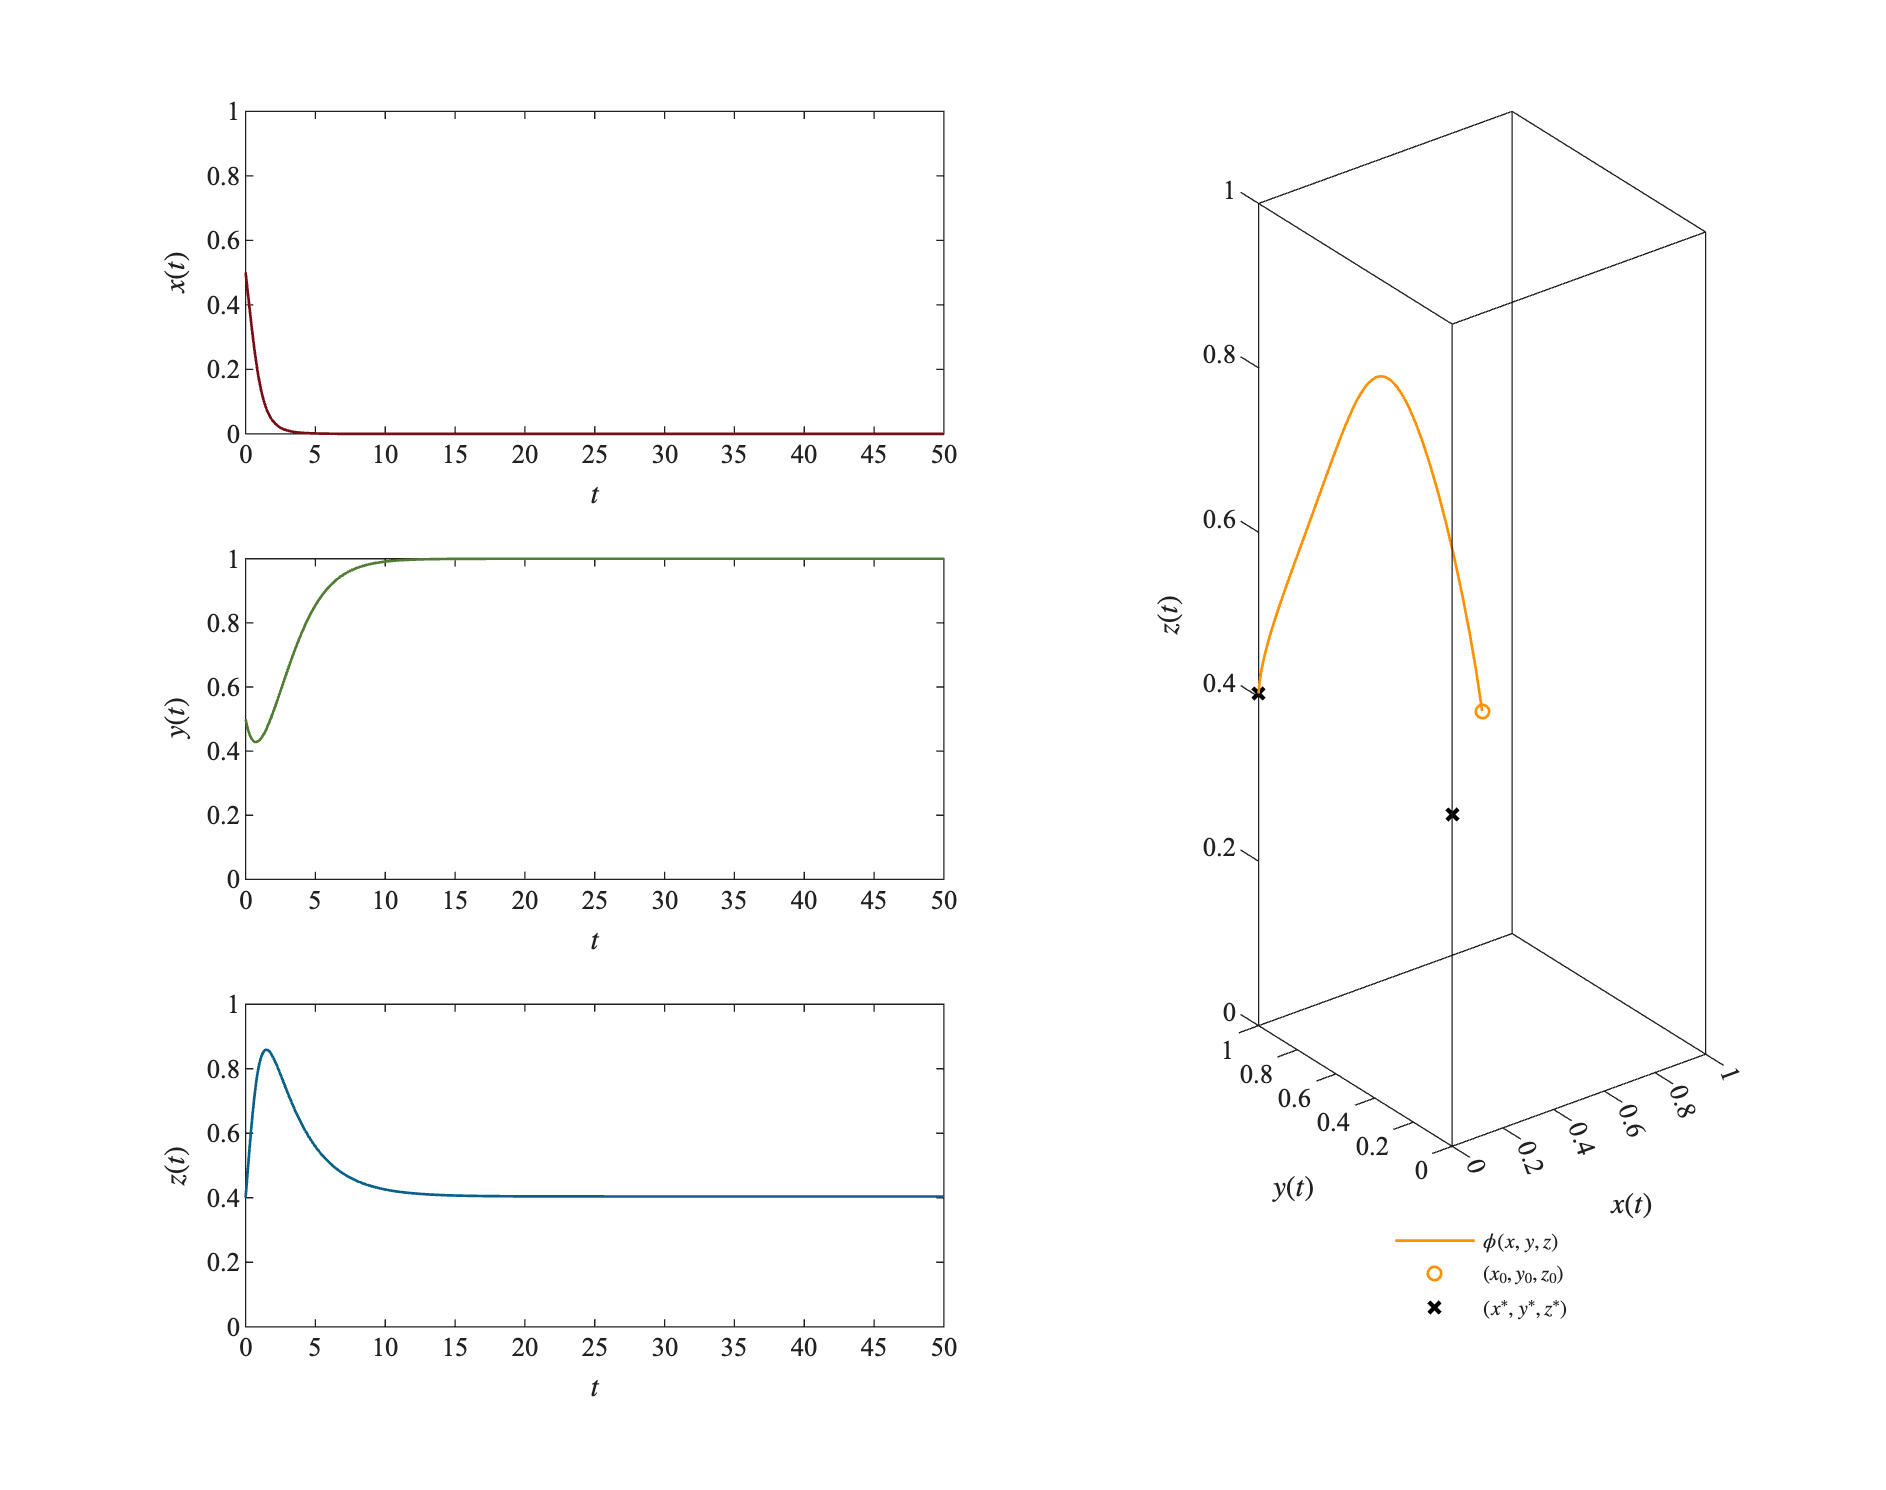


[t,x,y,z] = odesolver('Runge-Kutta',f0,par,rho,tend,dt);

plotCCI(t,x,y,z,E5);...
    exportgraphics(gcf,'Global_Equilibrium.pdf','ContentType','vector')

### Funciones

### Funciones

#### Metodos numericos


function [t,x,y,z] = odesolver(method,f0,par,rhoi,tend,dt)
    method = lower(strtrim(method));

    % Condiciones iniciales
    x0 = f0(1);  y0 = f0(2);  z0 = f0(3);

    % Parametros del modelo
    r1 = par(1); b1 = par(2); a12 = par(3); a13 = par(4);
    r2 = par(5); b2 = par(6); a21 = par(7);
    r3 = par(8); a31 = par(9); d3 = par(10);

    % Inicializacion
    n = round(tend/dt);
    t = (0:n)'*dt;

    x = zeros(length(t),1); x(1) = x0;
    y = zeros(length(t),1); y(1) = y0;
    z = zeros(length(t),1); z(1) = z0;

    % Metodos numericos
    for i=1:n
        switch method

            % Metodo de Euler
            case "euler"
                [fx,fy,fz] = f(x(i),y(i),z(i),rhoi(i));

                x(i+1) = x(i) + fx*dt;
                y(i+1) = y(i) + fy*dt;
                z(i+1) = z(i) + fz*dt;

            % Metodo de Heun
            case "heun"
                [fx,fy,fz] = f(x(i),y(i),z(i),rhoi(i));

                xn = x(i) + fx*dt;
                yn = y(i) + fy*dt;
                zn = z(i) + fz*dt;

                [fxn,fyn,fzn] = f(xn,yn,zn,rhoi(i));

                x(i+1) = x(i) + (fx + fxn)*dt/2;
                y(i+1) = y(i) + (fy + fyn)*dt/2;
                z(i+1) = z(i) + (fz + fzn)*dt/2;

            % Metodo de Runge-Kutta de orden 4
            case "runge-kutta"
                [k1x,k1y,k1z] = f(x(i),y(i),z(i),rhoi(i));

                [k2x,k2y,k2z] = f( ...
                    x(i)+k1x*dt/2, ...
                    y(i)+k1y*dt/2, ...
                    z(i)+k1z*dt/2, ...
                    rhoi(i));

                [k3x,k3y,k3z] = f( ...
                    x(i)+k2x*dt/2, ...
                    y(i)+k2y*dt/2, ...
                    z(i)+k2z*dt/2, ...
                    rhoi(i));

                [k4x,k4y,k4z] = f( ...
                    x(i)+k3x*dt, ...
                    y(i)+k3y*dt, ...
                    z(i)+k3z*dt, ...
                    rhoi(i));

                x(i+1) = x(i) + ...
                    (k1x + 2*k2x + 2*k3x + k4x)*dt/6;

                y(i+1) = y(i) + ...
                    (k1y + 2*k2y + 2*k3y + k4y)*dt/6;

                z(i+1) = z(i) + ...
                    (k1z + 2*k2z + 2*k3z + k4z)*dt/6;

            otherwise
                error('Metodo numerico no reconocido.');
        end
    end

    % Sistema de ecuaciones diferenciales
    function [dx,dy,dz] = f(x,y,z,r)
        dx = r1*x*(1 - b1*x) - a12*x*y - a13*x*z;
        dy = r2*y*(1 - b2*y) - a21*x*y;
        dz = (r3 - a31)*x*z - d3*z + r;
    end

    % Reduccion de puntos para la salida
    h = 10;
    paso = max(1, round(1/(h*dt)));

    indices = unique([1:paso:length(t), length(t)]);

    t = t(indices);
    x = x(indices);
    y = y(indices);
    z = z(indices);

end


#### Soluciones y trajectorias



function plotEDOs(t,x,y,z)

    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[1,1,25,20])
    FS = 10;
    
    %colorhunt.co
    clrx = [121, 13, 22]/255;
    clry = [79, 125, 50]/255;
    clrz = [8, 98, 136]/255;
    clrxyz = [255, 145, 0]/255;
    
    % Solucion x(t)
    subplot(3,6,[1,2,3]); box on; hold on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',clrx)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$x(t)$','Interpreter','latex','FontSize',FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([0 1]); yticks(0:0.2:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
    % Solucion y(t)
    subplot(3,6,[7,8,9]); box on; hold on; grid off;
    plot(t,y,'-','LineWidth',1,'Color',clry)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','latex','FontSize',FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([0 1]); yticks(0:0.2:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
    % Solucion z(t)
    subplot(3,6,[13,14,15]); box on; hold on; grid off;
    plot(t,z,'-','LineWidth',1,'Color',clrz)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$z(t)$','Interpreter','latex','FontSize',FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([0 1]); yticks(0:0.2:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
    % Trayectoria tridimensional
    subplot(3,6,[5,6,11,12,17,18]);
    box on; hold on; grid off; view([-42,21])
    
    ax = gca;
    ax.BoxStyle = 'full';
    
    plot3(x,y,z,'-','LineWidth',1,'Color',clrxyz)
    plot3(x(1),y(1),z(1),'o', ...
        'LineWidth',1,'MarkerSize',5,'Color',clrxyz)
    
    xlim([0 1]); xticks(0:0.2:1)
    ylim([0 1]); yticks(0:0.2:1)
    zlim([0 1]); zticks(0:0.2:1)
    
    xlabel('$x(t)$','Interpreter','latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','latex','FontSize',FS)
    zlabel('$z(t)$','Interpreter','latex','FontSize',FS)
    
    set(gca,'FontName','Times New Roman','FontSize',FS)

end


function plotCCI(t,x,y,z,E)

set(figure(),'Color','w')
set(gcf,'Units','centimeters','Position',[1,1,25,20])
FS = 10;

% colorhunt.co
clrx = [121, 13, 22]/255;
clry = [79, 125, 50]/255;
clrz = [8, 98, 136]/255;
clrxyz = [255, 145, 0]/255;
clrE = [0, 0, 0];

% Solucion x(t)
subplot(3,6,[1,2,3]); box on; hold on; grid off;
plot(t,x,'-','LineWidth',1,'Color',clrx)
xlabel('$t$','Interpreter','latex','FontSize',FS)
ylabel('$x(t)$','Interpreter','latex','FontSize',FS)
xlim([0 inf]); xticks(0:t(end)/10:t(end))
ylim([0 1]); yticks(0:0.2:1)
set(gca,'FontName','Times New Roman','FontSize',FS)

% Solucion y(t)
subplot(3,6,[7,8,9]); box on; hold on; grid off;
plot(t,y,'-','LineWidth',1,'Color',clry)
xlabel('$t$','Interpreter','latex','FontSize',FS)
ylabel('$y(t)$','Interpreter','latex','FontSize',FS)
xlim([0 inf]); xticks(0:t(end)/10:t(end))
ylim([0 1]); yticks(0:0.2:1)
set(gca,'FontName','Times New Roman','FontSize',FS)

% Solucion z(t)
subplot(3,6,[13,14,15]); box on; hold on; grid off;
plot(t,z,'-','LineWidth',1,'Color',clrz)
xlabel('$t$','Interpreter','latex','FontSize',FS)
ylabel('$z(t)$','Interpreter','latex','FontSize',FS)
xlim([0 inf]); xticks(0:t(end)/10:t(end))
ylim([0 1]); yticks(0:0.2:1)
set(gca,'FontName','Times New Roman','FontSize',FS)

% Trayectoria tridimensional
subplot(3,6,[5,6,11,12,17,18]);
box on; hold on; grid off; view([-37.36 10.46])

ax = gca;
ax.BoxStyle = 'full';

% Trayectoria
plot3(x,y,z,'-','LineWidth',1,'Color',clrxyz)

% Condicion inicial
plot3(x(1),y(1),z(1),'o', ...
    'LineWidth',1,'MarkerSize',5,'Color',clrxyz)

% Puntos de equilibrio
plot3(E(:,1),E(:,2),E(:,3),'x', ...
    'LineWidth',1.5,'MarkerSize',6,'Color',clrE)

xlim([0 1]); xticks(0:0.2:1)
ylim([0 1]); yticks(0:0.2:1)
zlim([0 1]); zticks(0:0.2:1)

xlabel('$x(t)$','Interpreter','latex','FontSize',FS)
ylabel('$y(t)$','Interpreter','latex','FontSize',FS)
zlabel('$z(t)$','Interpreter','latex','FontSize',FS)

set(gca,'FontName','Times New Roman','FontSize',FS)

% Leyenda
L = legend('$\phi(x,y,z)$', ...
    '$(x_0,y_0,z_0)$', ...
    '$(x^*,y^*,z^*)$');

set(L,'Interpreter','latex','FontSize',8, ...
    'Location','SouthOutside', ...
    'Box','Off','Orientation','Vertical')

end


#### Parametros y condiciones iniciales


function D = getdata(dynamics)
    r1 = 1;    b1 = 1;    a13 = 2.5;
    r2 = 0.6;  b2 = 1;    a21 = 1.5;
    r3 = 3;    a31 = 0.3; d3 = 0.4;
    
    if dynamics == "chaos"
        a12 = 1;
        f0 = [0.555,0.148,0.172]; %[x0,y0,z0]
    elseif dynamics == "orbit"
        a12 = 0.9;
        f0 = [0.254781,0.115167,0.600527];
    elseif dynamics == "cyclei"
        a12 = 0.8;
        f0 = [0.2,0.6,0.1];
    elseif dynamics == "cyclee"
        a12 = 0.75;
        f0 = [0.4,0.2,0.4];
    elseif dynamics == "equilibrium"
        a12 = 0.5;
        f0 = [0.5,0.5,0.4];
    end
    
    par = [r1,b1,a12,a13,r2,b2,a21,r3,a31,d3];
    D.par = par;
    D.f0 = f0;
end



Equilibrios

function [Eq,lambda] = equilibria(par,rho)

% Parametros del modelo
r1 = par(1); b1 = par(2); a12 = par(3); a13 = par(4);
r2 = par(5); b2 = par(6); a21 = par(7);
r3 = par(8); a31 = par(9); d3 = par(10);

rho = max(rho);

% =========================================================
% PUNTOS DE EQUILIBRIO
% =========================================================

e1=[(a31*r1 - r1*r3 + sqrt(r1*(r1*a31^2 + 2*r1*a31*b1*d3 - 4*a13*rho*a31*b1 - 2*r1*a31*r3 + r1*b1^2*d3^2 - 2*r1*b1*d3*r3 + 4*a13*rho*b1*r3 + r1*r3^2)) - b1*d3*r1)/(2*b1*r1*(a31 - r3)); 0; (a31*r1 - r1*r3 - sqrt(r1*(r1*a31^2 + 2*r1*a31*b1*d3 - 4*a13*rho*a31*b1 - 2*r1*a31*r3 + r1*b1^2*d3^2 - 2*r1*b1*d3*r3 + 4*a13*rho*b1*r3 + r1*r3^2)) + b1*d3*r1)/(2*a13*(a31 - r3))];
e2=[-(sqrt(a12^2*a21^2*d3^2 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + a12^2*a31^2*r2^2 - 2*a12^2*a31*r2^2*r3 + a12^2*r2^2*r3^2 - 2*a12*a21*a31*b2*d3*r1*r2 + 4*a13*rho*a12*a21*a31*b2*r2 - 2*a12*a21*b1*b2*d3^2*r1*r2 + 2*a12*a21*b2*d3*r1*r2*r3 - 4*a13*rho*a12*a21*b2*r2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 2*a12*b2*r1*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 4*a13*rho*a31*b1*b2^2*r1*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*rho*b1*b2^2*r1*r2^2*r3 + b2^2*r1^2*r2^2*r3^2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3)); (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*(sqrt(a12^2*a21^2*d3^2 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + a12^2*a31^2*r2^2 - 2*a12^2*a31*r2^2*r3 + a12^2*r2^2*r3^2 - 2*a12*a21*a31*b2*d3*r1*r2 + 4*a13*rho*a12*a21*a31*b2*r2 - 2*a12*a21*b1*b2*d3^2*r1*r2 + 2*a12*a21*b2*d3*r1*r2*r3 - 4*a13*rho*a12*a21*b2*r2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 2*a12*b2*r1*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 4*a13*rho*a31*b1*b2^2*r1*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*rho*b1*b2^2*r1*r2^2*r3 + b2^2*r1^2*r2^2*r3^2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3)); -(sqrt(a12^2*a21^2*d3^2 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + a12^2*a31^2*r2^2 - 2*a12^2*a31*r2^2*r3 + a12^2*r2^2*r3^2 - 2*a12*a21*a31*b2*d3*r1*r2 + 4*a13*rho*a12*a21*a31*b2*r2 - 2*a12*a21*b1*b2*d3^2*r1*r2 + 2*a12*a21*b2*d3*r1*r2*r3 - 4*a13*rho*a12*a21*b2*r2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 2*a12*b2*r1*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 4*a13*rho*a31*b1*b2^2*r1*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*rho*b1*b2^2*r1*r2^2*r3 + b2^2*r1^2*r2^2*r3^2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3))];
e3=[(sqrt(a12^2*a21^2*d3^2 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + a12^2*a31^2*r2^2 - 2*a12^2*a31*r2^2*r3 + a12^2*r2^2*r3^2 - 2*a12*a21*a31*b2*d3*r1*r2 + 4*a13*rho*a12*a21*a31*b2*r2 - 2*a12*a21*b1*b2*d3^2*r1*r2 + 2*a12*a21*b2*d3*r1*r2*r3 - 4*a13*rho*a12*a21*b2*r2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 2*a12*b2*r1*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 4*a13*rho*a31*b1*b2^2*r1*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*rho*b1*b2^2*r1*r2^2*r3 + b2^2*r1^2*r2^2*r3^2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3)); (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*(sqrt(a12^2*a21^2*d3^2 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + a12^2*a31^2*r2^2 - 2*a12^2*a31*r2^2*r3 + a12^2*r2^2*r3^2 - 2*a12*a21*a31*b2*d3*r1*r2 + 4*a13*rho*a12*a21*a31*b2*r2 - 2*a12*a21*b1*b2*d3^2*r1*r2 + 2*a12*a21*b2*d3*r1*r2*r3 - 4*a13*rho*a12*a21*b2*r2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 2*a12*b2*r1*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 4*a13*rho*a31*b1*b2^2*r1*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*rho*b1*b2^2*r1*r2^2*r3 + b2^2*r1^2*r2^2*r3^2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3)); (sqrt(a12^2*a21^2*d3^2 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + a12^2*a31^2*r2^2 - 2*a12^2*a31*r2^2*r3 + a12^2*r2^2*r3^2 - 2*a12*a21*a31*b2*d3*r1*r2 + 4*a13*rho*a12*a21*a31*b2*r2 - 2*a12*a21*b1*b2*d3^2*r1*r2 + 2*a12*a21*b2*d3*r1*r2*r3 - 4*a13*rho*a12*a21*b2*r2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 2*a12*b2*r1*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 4*a13*rho*a31*b1*b2^2*r1*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*rho*b1*b2^2*r1*r2^2*r3 + b2^2*r1^2*r2^2*r3^2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3))];
e4=[0; 1/b2; rho/d3];
e5=[-(r1*r3 - a31*r1 + sqrt(r1*(r1*a31^2 + 2*r1*a31*b1*d3 - 4*a13*rho*a31*b1 - 2*r1*a31*r3 + r1*b1^2*d3^2 - 2*r1*b1*d3*r3 + 4*a13*rho*b1*r3 + r1*r3^2)) + b1*d3*r1)/(2*b1*r1*(a31 - r3)); 0; (a31*r1 - r1*r3 + sqrt(r1*(r1*a31^2 + 2*r1*a31*b1*d3 - 4*a13*rho*a31*b1 - 2*r1*a31*r3 + r1*b1^2*d3^2 - 2*r1*b1*d3*r3 + 4*a13*rho*b1*r3 + r1*r3^2)) + b1*d3*r1)/(2*a13*(a31 - r3))];
e6=[0; 0; rho/d3];

% Conservar aqui las expresiones originales de:
% e1, e2, e3, e4, e5 y e6


% =========================================================
% EQUILIBRIOS NUMERICOS
% =========================================================

E = [e1,e2,e3,e4,e5,e6];
E = double(E)';
E(E > -1e-12 & E < 1e-12) = 0;

names = {'eq1','eq2','eq3','eq4','eq5','eq6'};

fprintf('\n%-12s %12s %12s %12s\n', ...
    'Equilibria', 'x*', 'y*', 'z*');

for i = 1:size(E,1)
    fprintf('%-12s %12.3e %12.3e %12.3e\n', ...
        names{i}, E(i,1), E(i,2), E(i,3));
end


% =========================================================
% CALCULO DEL JACOBIANO Y AUTOVALORES
% =========================================================

x = E(:,1);
y = E(:,2);
z = E(:,3);

n = size(E,1);

lr = zeros(n,3);
li = zeros(n,3);
stability = cell(n,1);

for i = 1:n

    % Matriz Jacobiana evaluada en cada equilibrio
    J = [
        r1-2*r1*b1*x(i)-a12*y(i)-a13*z(i), ...
        -a12*x(i), -a13*x(i);

        -a21*y(i), ...
        r2-2*r2*b2*y(i)-a21*x(i), 0;

        (r3-a31)*z(i), ...
        0, (r3-a31)*x(i)-d3
    ];

    % Calcular autovalores
    eigJ = eig(J);

    lr(i,:) = real(eigJ).';
    li(i,:) = imag(eigJ).';

    % Eliminar errores numericos cercanos a cero
    lr(i,abs(lr(i,:)) < 1e-12) = 0;
    li(i,abs(li(i,:)) < 1e-12) = 0;

    % Clasificar estabilidad
    if all(lr(i,:) < 0)

        stability{i,1} = 'stable';

    elseif any(lr(i,:) > 0)

        stability{i,1} = 'unstable';

    else

        stability{i,1} = 'unidentified';

    end

end


% =========================================================
% AUTOVALORES COMPLEJOS
% =========================================================

lambda = lr + 1i*li;


% =========================================================
% TABLA DE AUTOVALORES Y ESTABILIDAD
% =========================================================

fprintf('\n\n%-10s | %-16s | %-16s | %-16s | %-12s\n', ...
    'Equilibria', 'lambda 1', 'lambda 2', ...
    'lambda 3', 'stability');

fprintf('-----------------------------------------------------------------------------------------------\n');

for i = 1:n

    fprintf('%-10s  %+.1e%+.1ei  %+.1e%+.1ei  %+.1e%+.1ei  %-12s\n', ...
        names{i}, ...
        real(lambda(i,1)), imag(lambda(i,1)), ...
        real(lambda(i,2)), imag(lambda(i,2)), ...
        real(lambda(i,3)), imag(lambda(i,3)), ...
        stability{i});

end


% =========================================================
% ARGUMENTOS DE SALIDA
% =========================================================

Eq = E;

end